%% Identificação ARMAX para Sistema de Primeira Ordem
% Autor: [Seu Nome]
% Descrição: Identificação de modelo ARMAX para FT 0.02/(791s + 1) com Kp=180, Ki=0.18

close all; clear; clc;

%% 1. Definição da Função de Transferência Contínua e Discretização
G_cont = tf(0.02, [791 1]);  % FT contínua: 0.02 / (791s + 1)
Ts = 1;  % Período de amostragem
G_disc = c2d(G_cont, Ts, 'zoh');  % Discretização com ZOH
[numd, dend] = tfdata(G_disc, 'v');  % Coeficientes do numerador e denominador

disp('Função de Transferência Discreta:');

Função de Transferência Discreta:


disp(G_disc);

  tf with properties:

       Numerator: {[0 2.5268e-05]}
     Denominator: {[1 -0.9987]}
        Variable: 'z'
         IODelay: [0]
      InputDelay: [0]
     OutputDelay: [0]
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: [1]
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




%% 2. Controlador PI Discreto (Kp = 180, Ki = 0.18)
Kp = 180;
Ki = 0.18;
C_cont = tf([Kp Ki], [1 0]);  % Controlador PI contínuo
C_disc = c2d(C_cont, Ts, 'tustin');  % Discretização com Tustin
[numc, denc] = tfdata(C_disc, 'v');

disp('Controlador PI Discreto:');

Controlador PI Discreto:


disp(C_disc);

  tf with properties:

       Numerator: {[180.0900 -179.9100]}
     Denominator: {[1 -1]}
        Variable: 'z'
         IODelay: [0]
      InputDelay: [0]
     OutputDelay: [0]
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: [1]
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



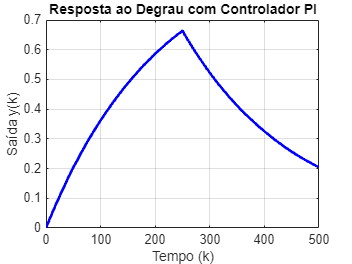


%% 3. Simulação da Malha Fechada
N = 500;
t = (0:N-1)*Ts;
u = [ones(N/2,1); zeros(N/2,1)] + 0.01*randn(N,1);  % Degrau + ruído

sys_cl = feedback(G_disc*C_disc, 1);  % Malha fechada
y = lsim(sys_cl, u, t);  % Simulação

figure(1)
plot(t, y, 'b', 'LineWidth', 2);
xlabel('Tempo (k)');
ylabel('Saída y(k)');
title('Resposta ao Degrau com Controlador PI');
grid on;

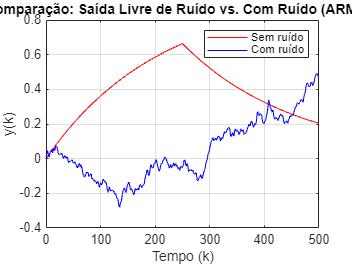


%% 4. Geração de Dados com Ruído (inclui erro autoregressivo)
e = 0.01*randn(N,1);  % Ruído branco
y_noisy = zeros(N,1);
for k = 2:N
    y_noisy(k) = -dend(2)*y_noisy(k-1) + numd(1)*u(k-1) + e(k) + 0.5*e(k-1); % erro AR(1)
end

figure(2)
plot(t, y, 'r', t, y_noisy, 'b');
legend('Sem ruído', 'Com ruído');
xlabel('Tempo (k)');
ylabel('y(k)');
title('Comparação: Saída Livre de Ruído vs. Com Ruído (ARMAX)');
grid on;


%% 5. Identificação ARMAX(na=1, nb=1, nc=1)
na = 1; nb = 1; nc = 1; nk = 1;
phi_armax = [];
Y_armax = [];
for k = max([na nb+nk nc])+1:N
    phi_k = [-y_noisy(k-1); u(k-nk); -e(k-1)];
    phi_armax = [phi_armax; phi_k'];
    Y_armax = [Y_armax; y_noisy(k)];
end

% Estimação por MQ
theta_armax = pinv(phi_armax)*Y_armax;
a1 = theta_armax(1);
b1 = theta_armax(2);
c1 = theta_armax(3);

disp('Parâmetros ARMAX identificados:');

Parâmetros ARMAX identificados:


disp(['a1 = ', num2str(a1)]);

a1 = -1.0014


disp(['b1 = ', num2str(b1)]);

b1 = -4.106e-05


disp(['c1 = ', num2str(c1)]);

c1 = -0.56055


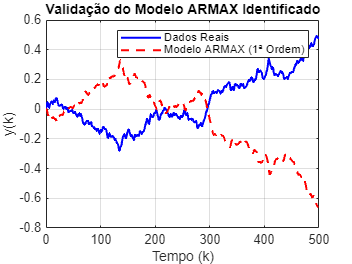


%% 6. Validação do modelo ARMAX
y_armax = zeros(N,1);
e_hat = zeros(N,1);

for k = 2:N
    e_hat(k) = y_noisy(k) - (-a1*y_noisy(k-1) + b1*u(k-1) + c1*e_hat(k-1));
    y_armax(k) = -a1*y_armax(k-1) + b1*u(k-1) + c1*e_hat(k-1);
end

figure(3)
plot(t, y_noisy, 'b', t, y_armax, 'r--', 'LineWidth', 1.5);
legend('Dados Reais', 'Modelo ARMAX (1ª Ordem)');
xlabel('Tempo (k)');
ylabel('y(k)');
title('Validação do Modelo ARMAX Identificado');
grid on;

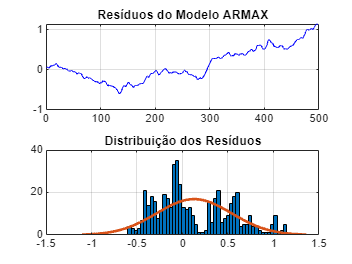


%% 7. Resíduos
residuos = y_noisy(max([na nb+nk nc])+1:N) - y_armax(max([na nb+nk nc])+1:N);
figure(4)
subplot(2,1,1)
plot(residuos, 'b');
title('Resíduos do Modelo ARMAX');
grid on;

subplot(2,1,2)
histfit(residuos, 50);
title('Distribuição dos Resíduos');
grid on;


%% 8. Equação ARMAX no Formato Geral (para Overleaf)
fprintf('\n--- Equação ARMAX de Primeira Ordem (Formato Geral) ---\n');


--- Equação ARMAX de Primeira Ordem (Formato Geral) ---


fprintf('y(k) = -a_1*y(k-1) + b_1*u(k-1) + c_1*e(k-1)\n');

y(k) = -a_1*y(k-1) + b_1*u(k-1) + c_1*e(k-1)


fprintf('a_1 = %.6f\n', a1);

a_1 = -1.001354


fprintf('b_1 = %.6f\n', b1);

b_1 = -0.000041


fprintf('c_1 = %.6f\n', c1);

c_1 = -0.560549



fprintf('\nCopie e cole no Overleaf:\n');


Copie e cole no Overleaf:


fprintf('\\begin{equation}\n');

\begin{equation}


fprintf('\\hat{y}(k) = %.4f \\cdot y(k-1) + %.4f \\cdot u(k-1) + %.4f \\cdot e(k-1)\n', -a1, b1, c1);

\hat{y}(k) = 1.0014 \cdot y(k-1) + -0.0000 \cdot u(k-1) + -0.5605 \cdot e(k-1)


fprintf('\\end{equation}\n');

\end{equation}
